# Solución de problemas:

### a) Método de punto fijo para el sistema no lineal:

disp("EJERCICIO A.");

EJERCICIO A.


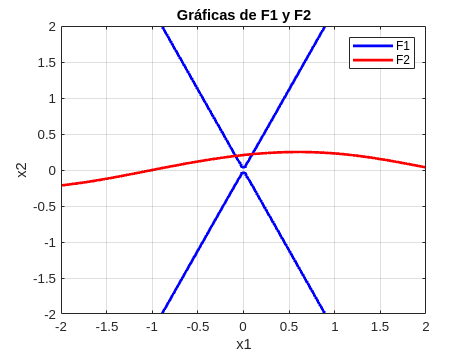

syms x1 x2
F1 = 5*x1^2 - x2^2;
F2 = x2 - 0.25*(sin(x1 + cos(x2)));
F1_func = matlabFunction(F1, 'Vars', {x1, x2});
F2_func = matlabFunction(F2, 'Vars', {x1, x2});
x1_vals = linspace(-2, 2, 100);
x2_vals = linspace(-2, 2, 100);
[X1, X2] = meshgrid(x1_vals, x2_vals);
Z1 = F1_func(X1, X2);
Z2 = F2_func(X1, X2);

figure;

contour(X1, X2, Z1, [0, 0], 'LineWidth', 2, 'Color', 'b', 'DisplayName', 'F1');
hold on;

% Graficar la segunda función con un color diferente (por ejemplo, rojo)
contour(X1, X2, Z2, [0, 0], 'LineWidth', 2, 'Color', 'r', 'DisplayName', 'F2');
% Ajustar la gráfica
xlabel('x1');
ylabel('x2');
title('Gráficas de F1 y F2');
legend('show');
grid on;
hold off;


n = 2;
vars = sym('x', [n, 1]);

G_sym = [sqrt((vars(2)^2) / 5); 0.25*(sin(vars(1))+cos(vars(2)))]

$$G\_sym = \left(\begin{array}{c} \sqrt{\frac{{x_{2}}^{2}}{5}}\\ \frac{\cos\left(x_{2}\right)}{4}+\frac{\sin\left(x_{1}\right)}{4} \end{array}\right)$$

G = matlabFunction(G_sym, 'Vars', {vars});



x0 = [0.25; 0.25];
itmax = 100;
tol = 10^-6;

[r, iter] = puntofijose(G, x0, itmax, tol)

Iteración	Valor de x1	Valor de x2
--------------------------------------------
0		0.250000	0.250000
1		0.111803	0.304079
2		0.135988	0.266423
3		0.119148	0.275072
4		0.123016	0.270318
5		0.120890	0.271598
6		0.121462	0.270985
7		0.121188	0.271168
8		0.121270	0.271088
9		0.121234	0.271113
10		0.121246	0.271103
11		0.121241	0.271106
12		0.121242	0.271105
13		0.121242	0.271105


r =     0.1212
    0.2711


iter = 13

### b) Método de Newton para el sistema de ecuaciones no lineales:

disp("EJERCICIO B.");

EJERCICIO B.


n = 3;
vars = sym('x', [n, 1]);
F_sym = [3*vars(1) - cos(vars(2)*vars(3)) - 1/2;
         vars(1)^2 - 81*(vars(2) + 0.1)^2 + sin(vars(3)) + 1.06;
         exp(1)^(-vars(1)*vars(2)) + 20*vars(3) + (10*pi - 3)/3];
F = matlabFunction(F_sym, 'Vars', {vars});
x0 = [0.1 0.1 -0.1];
[r, ~] = newtonse(F, x0, itmax, tol)

r =     0.5000
   -0.0000
   -0.5236


### c) Dado el sistema de ecuaciones no lineales:

disp("EJERCICIO C.");

EJERCICIO C.


n = 2;
vars = sym('x', [n, 1]);
F_sym = [vars(1)^2 + vars(2)^2 - 4;
     vars(1)*vars(2) - 1];
F = matlabFunction(F_sym, 'Vars', {vars});
x0 = [-2 1/2];
tol = 10^-4;
[r, ~] = newtonse(F, x0, itmax, tol)

r =    -1.9319
   -0.5176


### d) Utilice el método de Newton para aproximar el máximo de la función:

disp("EJERCICIO D.");

EJERCICIO D.


syms x y
F_sym = 2*x*y + 1.5*y -1.25*x^2 - 2*y^2;
grad_F = gradient(F_sym, [x, y]);
grad_F_func = matlabFunction(grad_F, 'Vars', {[x; y]});
X0 = [0; 0];
[r, ~] = newtonse(grad_F_func, X0, itmax, tol)

r =     0.5000
    0.6250


F_func = matlabFunction(F_sym, 'Vars', {[x; y]});
F_evaluado = F_func(r)

F_evaluado = 0.4688

### e) Presión:

disp("EJERCICIO E.");

EJERCICIO E.


n = 3;
k = sym('x', [n, 1]);
F_sym = [k(1)*(exp(1)^k(2))+k(3)-10;
         k(1)*(exp(1)^(k(2)*2))+k(3)*2-12;
         k(1)*(exp(1)^(k(2)*3))+k(3)*3-15;];
F = matlabFunction(F_sym, 'Vars', {k});
X0 = [2 2 2];
[r, ~] = newtonse(F, X0, itmax, tol)

r =     8.7713
    0.2597
   -1.3723


n = 1;

syms r_scalar
F_new = r(1)*exp(1)^(r(2)*r_scalar) + r(3)*r_scalar - (500/(pi*r_scalar^2));
F_numeric = matlabFunction(F_new, 'Vars', {r_scalar});

[r, ~] = newtonse(F_numeric, 1, itmax, tol)

r = 3.1852